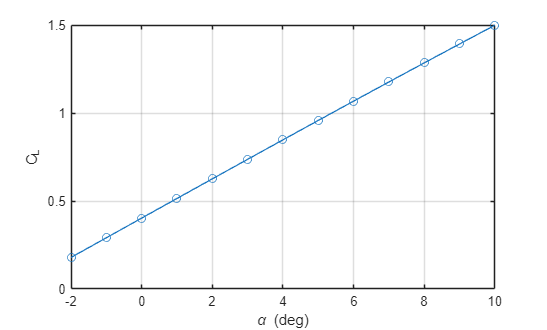

baseDir = fileparts(matlab.desktop.editor.getActiveFilename);
filePath = fullfile(baseDir, '../+lookup/+aerodynamics/cruise_lookup_table.mat');
S = load(filePath);
R = S.Results;

span = 73.5;
mach = 0.81;
rootChord = 15.2;
altitude = 9500;

span = S.spanVec(nearestIndex(S.spanVec,span));
mach = S.machVec(nearestIndex(S.machVec,mach));
rootChord = S.rootChordVec(nearestIndex(S.rootChordVec,rootChord));
altitude = S.altVec(nearestIndex(S.altVec,altitude));

i = [R.WingSpan] == span & [R.Mach] == mach & [R.RootChord] == rootChord & [R.Altitude] == altitude;

A = [R(i).Alpha];
CL = [R(i).CL];
CD = [R(i).CD];

[A,ord] = sort(A);
CL = CL(ord);
CD = CD(ord);

alpha = 2;  
CLq = interp1(A,CL,alpha,'linear','extrap');
CDq = interp1(A,CD,alpha,'linear','extrap');

figure
plot(A,CL,'-o')
xlabel('\alpha (deg)')
ylabel('C_L')
grid on

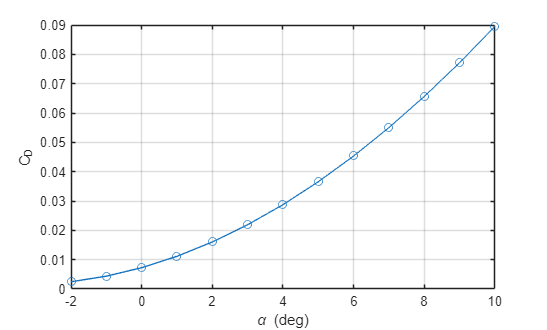


figure
plot(A,CD,'-o')
xlabel('\alpha (deg)')
ylabel('C_D')
grid on


function k = nearestIndex(vec,x)
[~,k] = min(abs(vec-x));
end